clear all;
clf reset;

data

xs = 2011:2021;
ys = [
    51.8, 56.6, 53.3, 55.6, 56.3, 56.2, ...
    56.1, 56.2, 53.6, 55.7, 56.3
];

xs = xs';
ys = ys';

plot

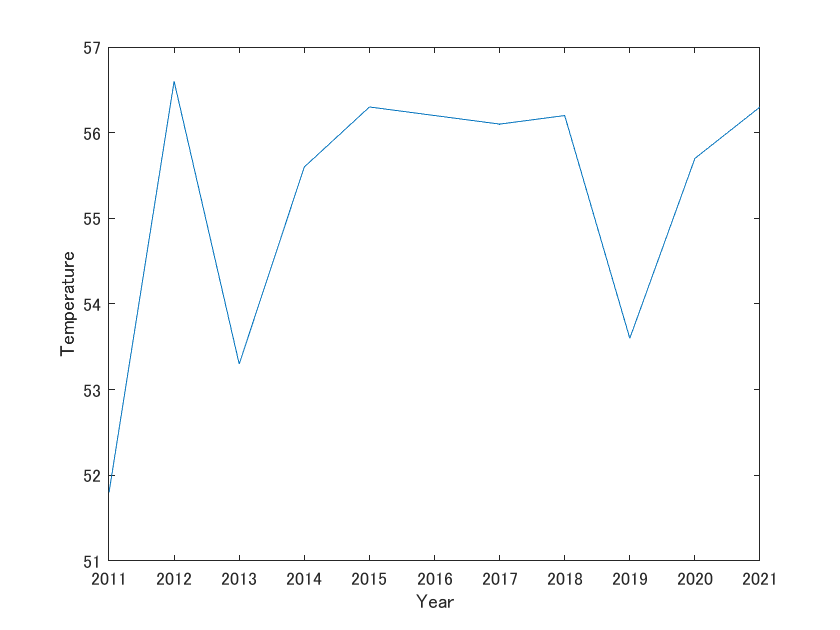

figure;
plot(xs, ys)
xlabel("Year")
ylabel("Temperature")

Least square

xsc = xs ./ 1000;
A = [ones(length(xsc), 1) xsc xsc.^2 xsc.^3 xsc.^4];
c = pinv(A) * ys;
c

c = 	1.0e+10 *

    4.0243
   -7.9945
    5.9556
   -1.9718
    0.2448



g = @(x) c(1)+c(2).*x+c(3).*x.^2+c(4).*x.^3+c(5).*x.^4;
newys = g(xs ./ 1000);
err = newys - ys;
disp("Mean error:")

Mean error:


disp(mean(abs(err)))

    0.8170



disp("Residual:")

Residual:


disp(sqrt(mean(abs(err) .^ 2)))

    1.1264



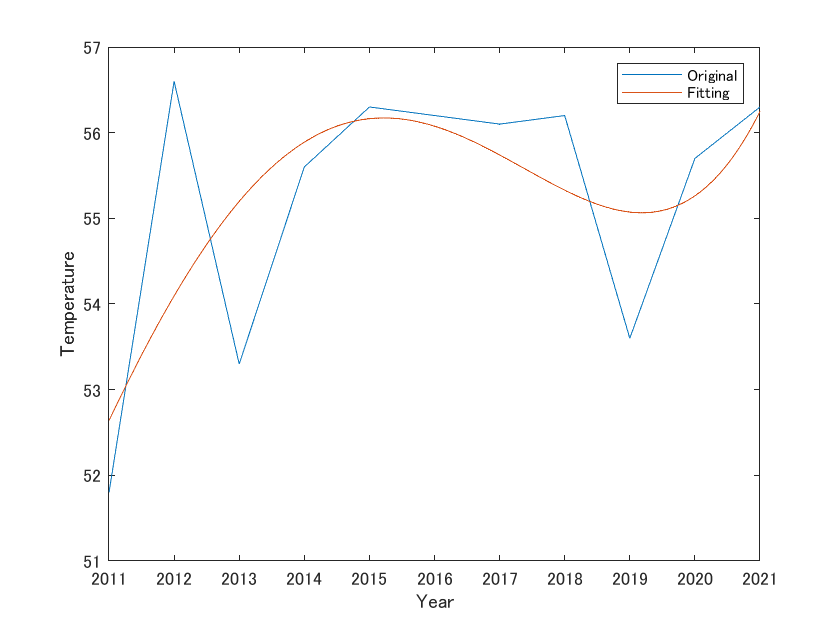


pltxs = 2011:0.01:2021;
pltys = g(pltxs ./ 1000);

figure;
plot(xs, ys);
hold on
plot(pltxs, pltys);
legend("Original", "Fitting")
xlabel("Year")
ylabel("Temperature")
hold off

Bezier

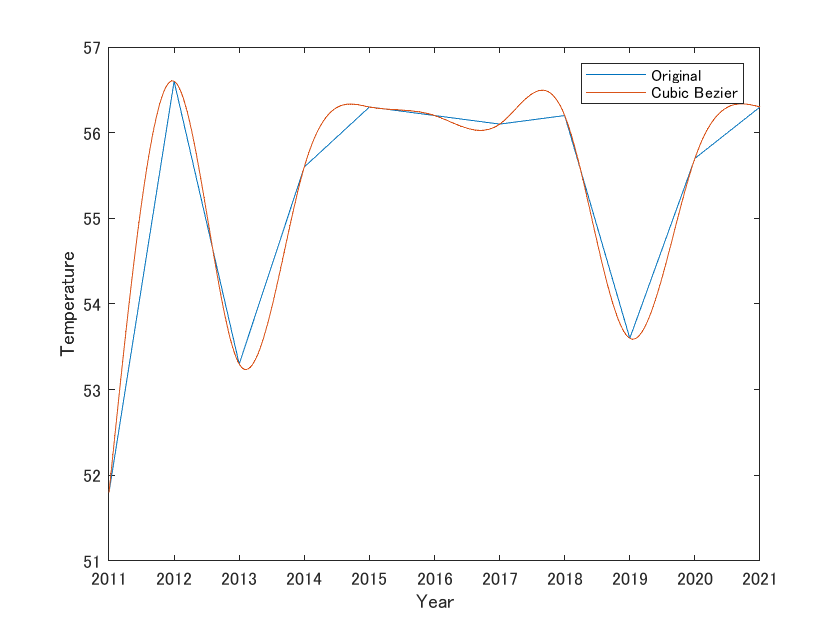

x = xs';
y = ys';

[xxs, yys] = cubic_spline(xs, ys, 0, 0, 0.01);
figure;
plot(xs, ys)
hold on 
plot(xxs, yys)
legend("Original", "Cubic Bezier")
xlabel("Year")
ylabel("Temperature")
hold off

funcs

function point = deCasteljau(u, pts, i, j)
    if i == 1
        point = pts(:, j);
    else
        point = u * deCasteljau(u, pts, i - 1, j) + (1 - u) * deCasteljau(u, pts, i - 1, j - 1);
    end
end

function [ XX,YY ] = cubic_spline( X,Y,C0,CN,hh )
    counter = 0;
    index = 1;
    
    n = max(size(X))-1;

    h = zeros(n,1);
    
    for k = 1:n
        h(k) = X(k+1) - X(k);
        for j = X(k):hh:X(k+1)-hh       
            counter = counter +1;
        end
    end
    
    my = zeros(n-1,1);
    lambda = zeros(n-1,1);
    delta_vor = zeros(n,1);
    
    for k = 1:n-1
        my(k) = h(k) / (h(k+1)+h(k));
        lambda(k) = h(k+1) / ( h(k+1)+h(k));
        delta_vor(k) = 6/(h(k+1)+h(k)) * ((Y(k+2)-Y(k+1))/h(k+1) - (((Y(k+1)-Y(k))/h(k))));
    end
    
    delta = [0;delta_vor];
    my_mat = [my;0];
    lambda_mat = [0;lambda];
    
    S = 2*eye(n+1) + diag(my_mat,-1) + diag(lambda_mat,1);
    
    M = S\delta;
    M(1) = C0;                             
    M(end) = CN;                 

    a = zeros(n,1);
    b = zeros(n,1);
    c = zeros(n,1);
    d = zeros(n,1);
    
    for k = 1:n
        a(k) = Y(k);
        b(k) = (Y(k+1)-Y(k))/h(k) - (h(k)/6) * (2*M(k)+M(k+1));
        c(k) = M(k)/2;
        d(k) = (M(k+1)-M(k))/(6*h(k));
    end
    
    c_Spline = @(x,i) a(i) + b(i).*(x-X(i)) + c(i).*(x-X(i)).^2 + d(i).*(x-X(i)).^3;
    
    XX = zeros(1,counter);
    YY = zeros(1,counter);
    
    for k = 1:n
        for j = X(k):hh:X(k+1)-hh
             XX(index) = j;
             YY(index) = c_Spline(j,k);
             index = index + 1;
        end
    end
    
    XX = [XX,X(end)];
    YY = [YY,c_Spline(X(end),n)];

end